## Generate 4-QAM Image Data

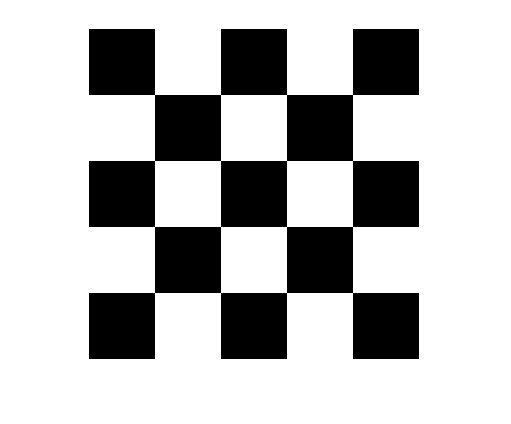

im = imread('data\checkerboard.jpg');
imBW = im2bw(im,.7);
figure;
imshow(imBW)


data = sign(reshape(imBW, 1, []));
dataH = addParity(data); %hamming code
dataQ = encodeQam(data);

## Generate TX Data

%generate start sequence
rng(1);
start_sequence_length = 32;
starter_sequence=sign(sign(randn(start_sequence_length,1))+1i*sign(randn(start_sequence_length,1)));

%generate RRC Pulse
T = 50; % Symbol Period
span = 20;
rolloff = 0.5;
rrc = rcosdesign(rolloff,span,T, 'sqrt');   % creates a root-raised cosine 
                                      % filter which when combined with a 
                                      % matched filter results in 
                                      % zero crossings every 
                                      % T. Rolloff factor of 0.5
                                      % 20 x 3 samples are returned 
                                      % (in theory the raised cosine
                                      % impulse response is infinite, but
                                      % is truncated to T x 20 samples)
rrc = rrc ./ max(rrc);

%combine start and data
dat= [starter_sequence.' dataQ.'].';
x_us=upsample(dat,T);
%pulse=ones(100,1);
pulse = rrc;
x=conv(x_us,pulse, 'same');

txname='data\tx_image_checkerboard.dat';
write_usrp_data_file(x,txname)

## Decode RX Data

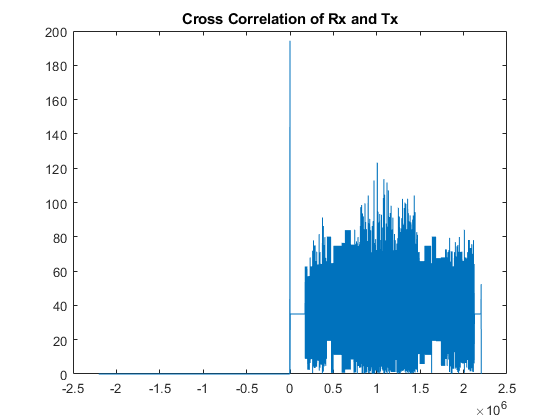

startPos = 0

Index exceeds the number of array elements (2201850).

Error in qpsk (line 21)
signal_rx = conv(read_shifted(1:packet_length),rrc,'same');

rxname = 'data\tx_image_einstein_Ham.dat';
[rxQ, errRate] = qpsk(txname, rxname, length(dataQ), T, 2000000);

errRate

## Printing Image

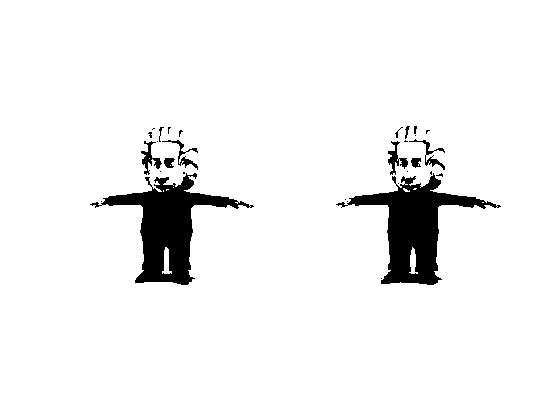

rxQ = sign(real(rxQ)) + 1i*sign(imag(rxQ));
rxBinary = decodeQam(rxQ);
rxH = errorCorrect(rxBinary);
rxH = rxH(1:end);
rxIm = reshape(rxH, 216, []);
subplot(1,2,1)
imshow(rxIm)
subplot(1,2,2)
imshow(imBW)